% Initialisation

Dot indexing is not supported for variables of this type.

Error in predictSVM (line 6)
            scores(j) = dot(models(j).w, X(i, :)) + models{j}.b;

SVM classifier trained.


Accuracy: 100%


Root Mean Square Error (RMSE): 0


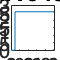

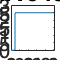

DT_data = smoothfirings; % Import data
num_cols = floor(size(DT_data, 2) / 15);
divided_matrices = cell(1, 15);
labels = [];

% Divide data into original 15 files
for i = 1:15
    start_col = (i - 1) * num_cols + 1;
    end_col = i * num_cols;
    divided_matrices{i} = DT_data(:, start_col:end_col);
    
    if i <= 3
        label = 1;
    elseif i <= 7
        label = 2;
    elseif i <= 12
        label = 3;
    else
        label = 4;
    end
    
    labels = [labels, repmat(label, 1, num_cols)];
end

% Concatenate training matrix
training_data = horzcat(divided_matrices{:});
feature_vectors = sum(training_data);

% Threshold for nois spikes
noise_threshold = 0.1;
labels(feature_vectors < noise_threshold) = 0;

% Initialize for cross-validation
k = 5; % Number of folds
indices = crossvalind('Kfold', labels, k);
accuracy = zeros(1, k);
rmse = zeros(1, k);

for i = 1:k
    test = (indices == i);
    train = ~test;
    
    % Defining test/training data
    X_train = feature_vectors(train)';
    y_train = labels(train)';
    X_test = feature_vectors(test)';
    y_test = labels(test)';
   
    % Traininig and testing functions for SVM classifier
    classifier = trainSVM(X_train, y_train);
    y_pred = predictSVM(classifier, X_test);
    
    % Iterative accuracy and RMSE
    accuracy(i) = sum(y_pred == y_test) / length(y_test);
    rmse(i) = sqrt(mean((y_pred - y_test).^2));
    
end


% Average accuracy and RMSE over iterations
mean_accuracy = mean(accuracy);
mean_rmse = mean(rmse);

disp(['Average Accuracy: ', num2str(mean_accuracy * 100), '%']);

Average Accuracy: 0.033086%


disp(['Average RMSE: ', num2str(mean_rmse)]);

Average RMSE: 0.99983
